# **Matlab案例代码解析**

## 3. 科学计算案例

### 3.1 数值分析

#### 3.1.7 Trapezoidal数值积分问题

颜值即正义；

**颜色模板参考：**[**60套优雅的颜色模板**](https://zhuanlan.zhihu.com/p/444970597)

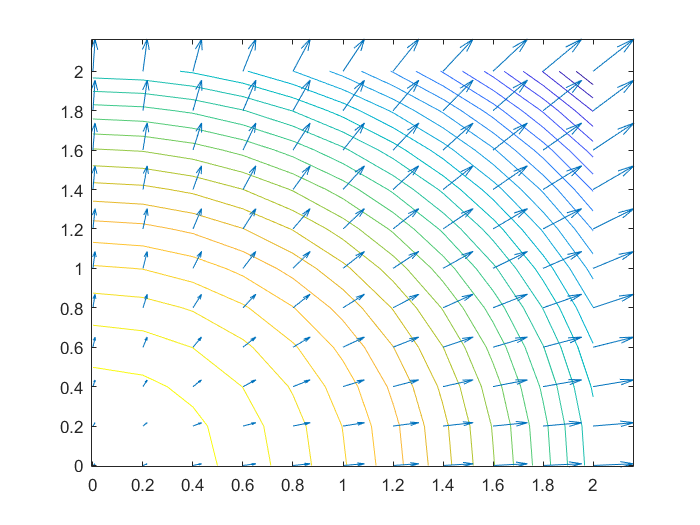

clear; clc; close all;
% 问题1
syms x y
% 符号函数
z(x, y) = 4 - x^2 - y^2;
% z(x, y) = (x^2 - 2*x) * exp(-x^2 - y^2 - x*y);
% 数据网格化
xR = 0:0.2:2;
yR = 0:0.2:2;
[x0, y0] = meshgrid(xR, yR);
z0 = double(z(x0, y0));
% 梯度的数值计算
[fx, fy] = gradient(z0);
fx = fx / 0.2;
fy = fy / 0.2;
% 画图
figure
contour(x0, y0, z0, 30);
hold on
quiver(x0, y0, -fx, -fy);
hold off

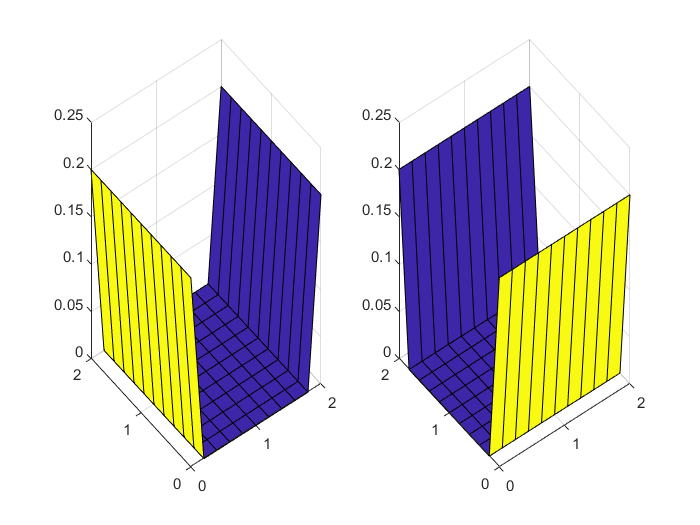

% 梯度理论值
zx = diff(z, x);
zy = diff(z, y);
zx0 = double(zx(x0, y0));
zy0 = double(zy(x0, y0));
% 绘制误差曲面
figure
subplot(1, 2, 1);
surf(x0, y0, abs(fx - zx0));
subplot(1, 2, 2);
surf(x0, y0, abs(fy - zy0));

% 问题2
% 理论值
I1 = trapz(yR, trapz(xR, z0, 2)); 
% 数值积分
% 二重积分可视为求特定区间的体积，底为 x 和 y 构成的区域，高为z
% 思路：计算每个网格的体积，然后将所有网格的体积累加就是积分值
% 单个网格的体积可表示为：底×高
% 高可以用均值表示
I2 = 0;
for i = 1 : length(x0) - 1
    for j = 1 : length(y0) - 1
        s = 0.2 * 0.2;
        h = (z0(i, j) + z0(i, j+1) + z0(i+1, j) + z0(i+1, j+1)) / 4;
        I2 = I2 + s*h;
    end
end
% 计算误差
% 误差几乎为零，查阅 matlab 帮助文档可知，trapz函数在计算积分时采用的是
% 梯度公式，此处我也此采用的梯度公式，因此两者计算结果一致
err = abs(I1 - I2);
disp(err)

   2.6645e-15

